**Model Selection Example with D2O Calibraion Data**

Aim is to use Bayesian model selection to determine is a calibration sample is a clean surface.

First analyse a fit with no layers. So fit interfacial roughness, background and scalefactor. Rather than build the model from scratch, we get the inputs into RAT by converting an existing Rascal 1 project...

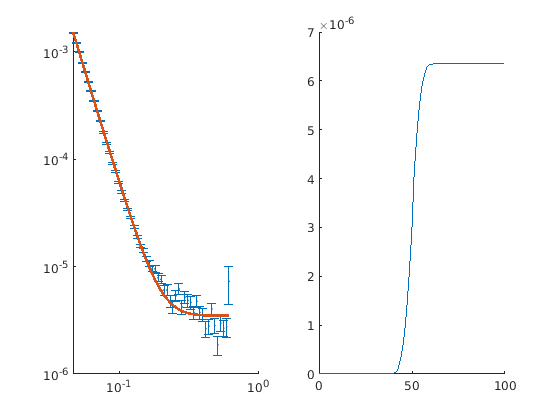

clear;
[problem,controls] = r1ToProblemDef('D2O.mat');
[out1,out2] = RAT(problem,controls);
plotRefSLD(out1,out2)

We want to run the nested sampler, so we choose this as the procedure in controls..

controls.procedure = 'NS'

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'NS'
    calcSldDuringFit: 'no'
               Nlive: 50
               Nmcmc: 0
           propScale: 0.1000
         nsTolerance: 1


Now we just call RAT to run the nested sampler..

[out1,out2] = RAT(problem,controls);

log(Z): -2.37810e+05, tol = 2.37799e+05, K = 1, iteration = 1, H = NaN
log(Z): -2.14373e+05, tol = 2.14362e+05, K = 1, iteration = 2, H = 3.942006e+00
log(Z): -2.14309e+05, tol = 2.14297e+05, K = 1, iteration = 3, H = 3.962006e+00
log(Z): -2.08453e+05, tol = 2.08443e+05, K = 1, iteration = 4, H = 3.982006e+00
log(Z): -2.05977e+05, tol = 2.05967e+05, K = 1, iteration = 5, H = 4.002006e+00
log(Z): -1.78331e+05, tol = 1.78321e+05, K = 1, iteration = 6, H = 4.022006e+00
log(Z): -1.76697e+05, tol = 1.76687e+05, K = 1, iteration = 7, H = 4.042006e+00
log(Z): -1.63196e+05, tol = 1.63186e+05, K = 1, iteration = 8, H = 4.062006e+00
log(Z): -1.57522e+05, tol = 1.57512e+05, K = 1, iteration = 9, H = 4.082006e+00
log(Z): -1.30309e+05, tol = 1.30299e+05, K = 1, iteration = 10, H = 4.102006e+00
log(Z): -1.25393e+05, tol = 1.25383e+05, K = 1, iteration = 11, H = 4.122006e+00
log(Z): -1.23232e+05, tol = 1.23222e+05, K = 1, iteration = 12, H = 4.142006e+00
log(Z): -1.21715e+05, tol = 1.21704e+05, K = 1


noLayer_logX = out2.logX

noLayer_logX = -9.8127

..this output value is the **Bayesian evidence.**

Now we need to repeat this with a 1 layer model. Again, for simplicity we will convert a pre-prepared R1 model...

[problem,controls] = r1ToProblemDef('D2O_1layer.mat');
controls.procedure = 'NS';
problem.backgroundFitYesNo = 1;
problem.scalefactorFitYesNo = 1;
[out1_layer, out2_layer] = RAT(problem,controls);

log(Z): -2.59924e+05, tol = 2.59915e+05, K = 1, iteration = 1, H = NaN
log(Z): -1.79538e+05, tol = 1.79528e+05, K = 1, iteration = 2, H = 3.942006e+00
log(Z): -1.70427e+05, tol = 1.70418e+05, K = 1, iteration = 3, H = 3.962006e+00
log(Z): -1.64525e+05, tol = 1.64515e+05, K = 1, iteration = 4, H = 3.982006e+00
log(Z): -1.57063e+05, tol = 1.57054e+05, K = 1, iteration = 5, H = 4.002006e+00
log(Z): -1.54527e+05, tol = 1.54517e+05, K = 1, iteration = 6, H = 4.022006e+00
log(Z): -1.42442e+05, tol = 1.42433e+05, K = 1, iteration = 7, H = 4.042006e+00
log(Z): -1.41684e+05, tol = 1.41674e+05, K = 1, iteration = 8, H = 4.062006e+00
log(Z): -1.35685e+05, tol = 1.35675e+05, K = 1, iteration = 9, H = 4.082006e+00
log(Z): -1.25640e+05, tol = 1.25630e+05, K = 1, iteration = 10, H = 4.102006e+00
log(Z): -1.24113e+05, tol = 1.24103e+05, K = 1, iteration = 11, H = 4.122006e+00
log(Z): -1.19972e+05, tol = 1.19962e+05, K = 1, iteration = 12, H = 4.142006e+00
log(Z): -1.01813e+05, tol = 1.01804e+05, K = 1

layer_logx = out2_layer.logX

layer_logx = -10.4361

Now, to work out the odds ratio....

oddsRatio = exp(abs(layer_logx) - abs(noLayer_logX));
confidenceLevel = (oddsRatio/(1 + oddsRatio))*100;

fprintf('This is a clean surface with a confidence level of %2.2f precent',confidenceLevel)

This is a clean surface with a confidence level of 65.10 precent